population/gdp data

clf
lcc_pop_gdp_country = readtable('../stats/lcc_pop_gdp_country.csv','ReadRowNames',true);

nodes number vs population colored by GDP

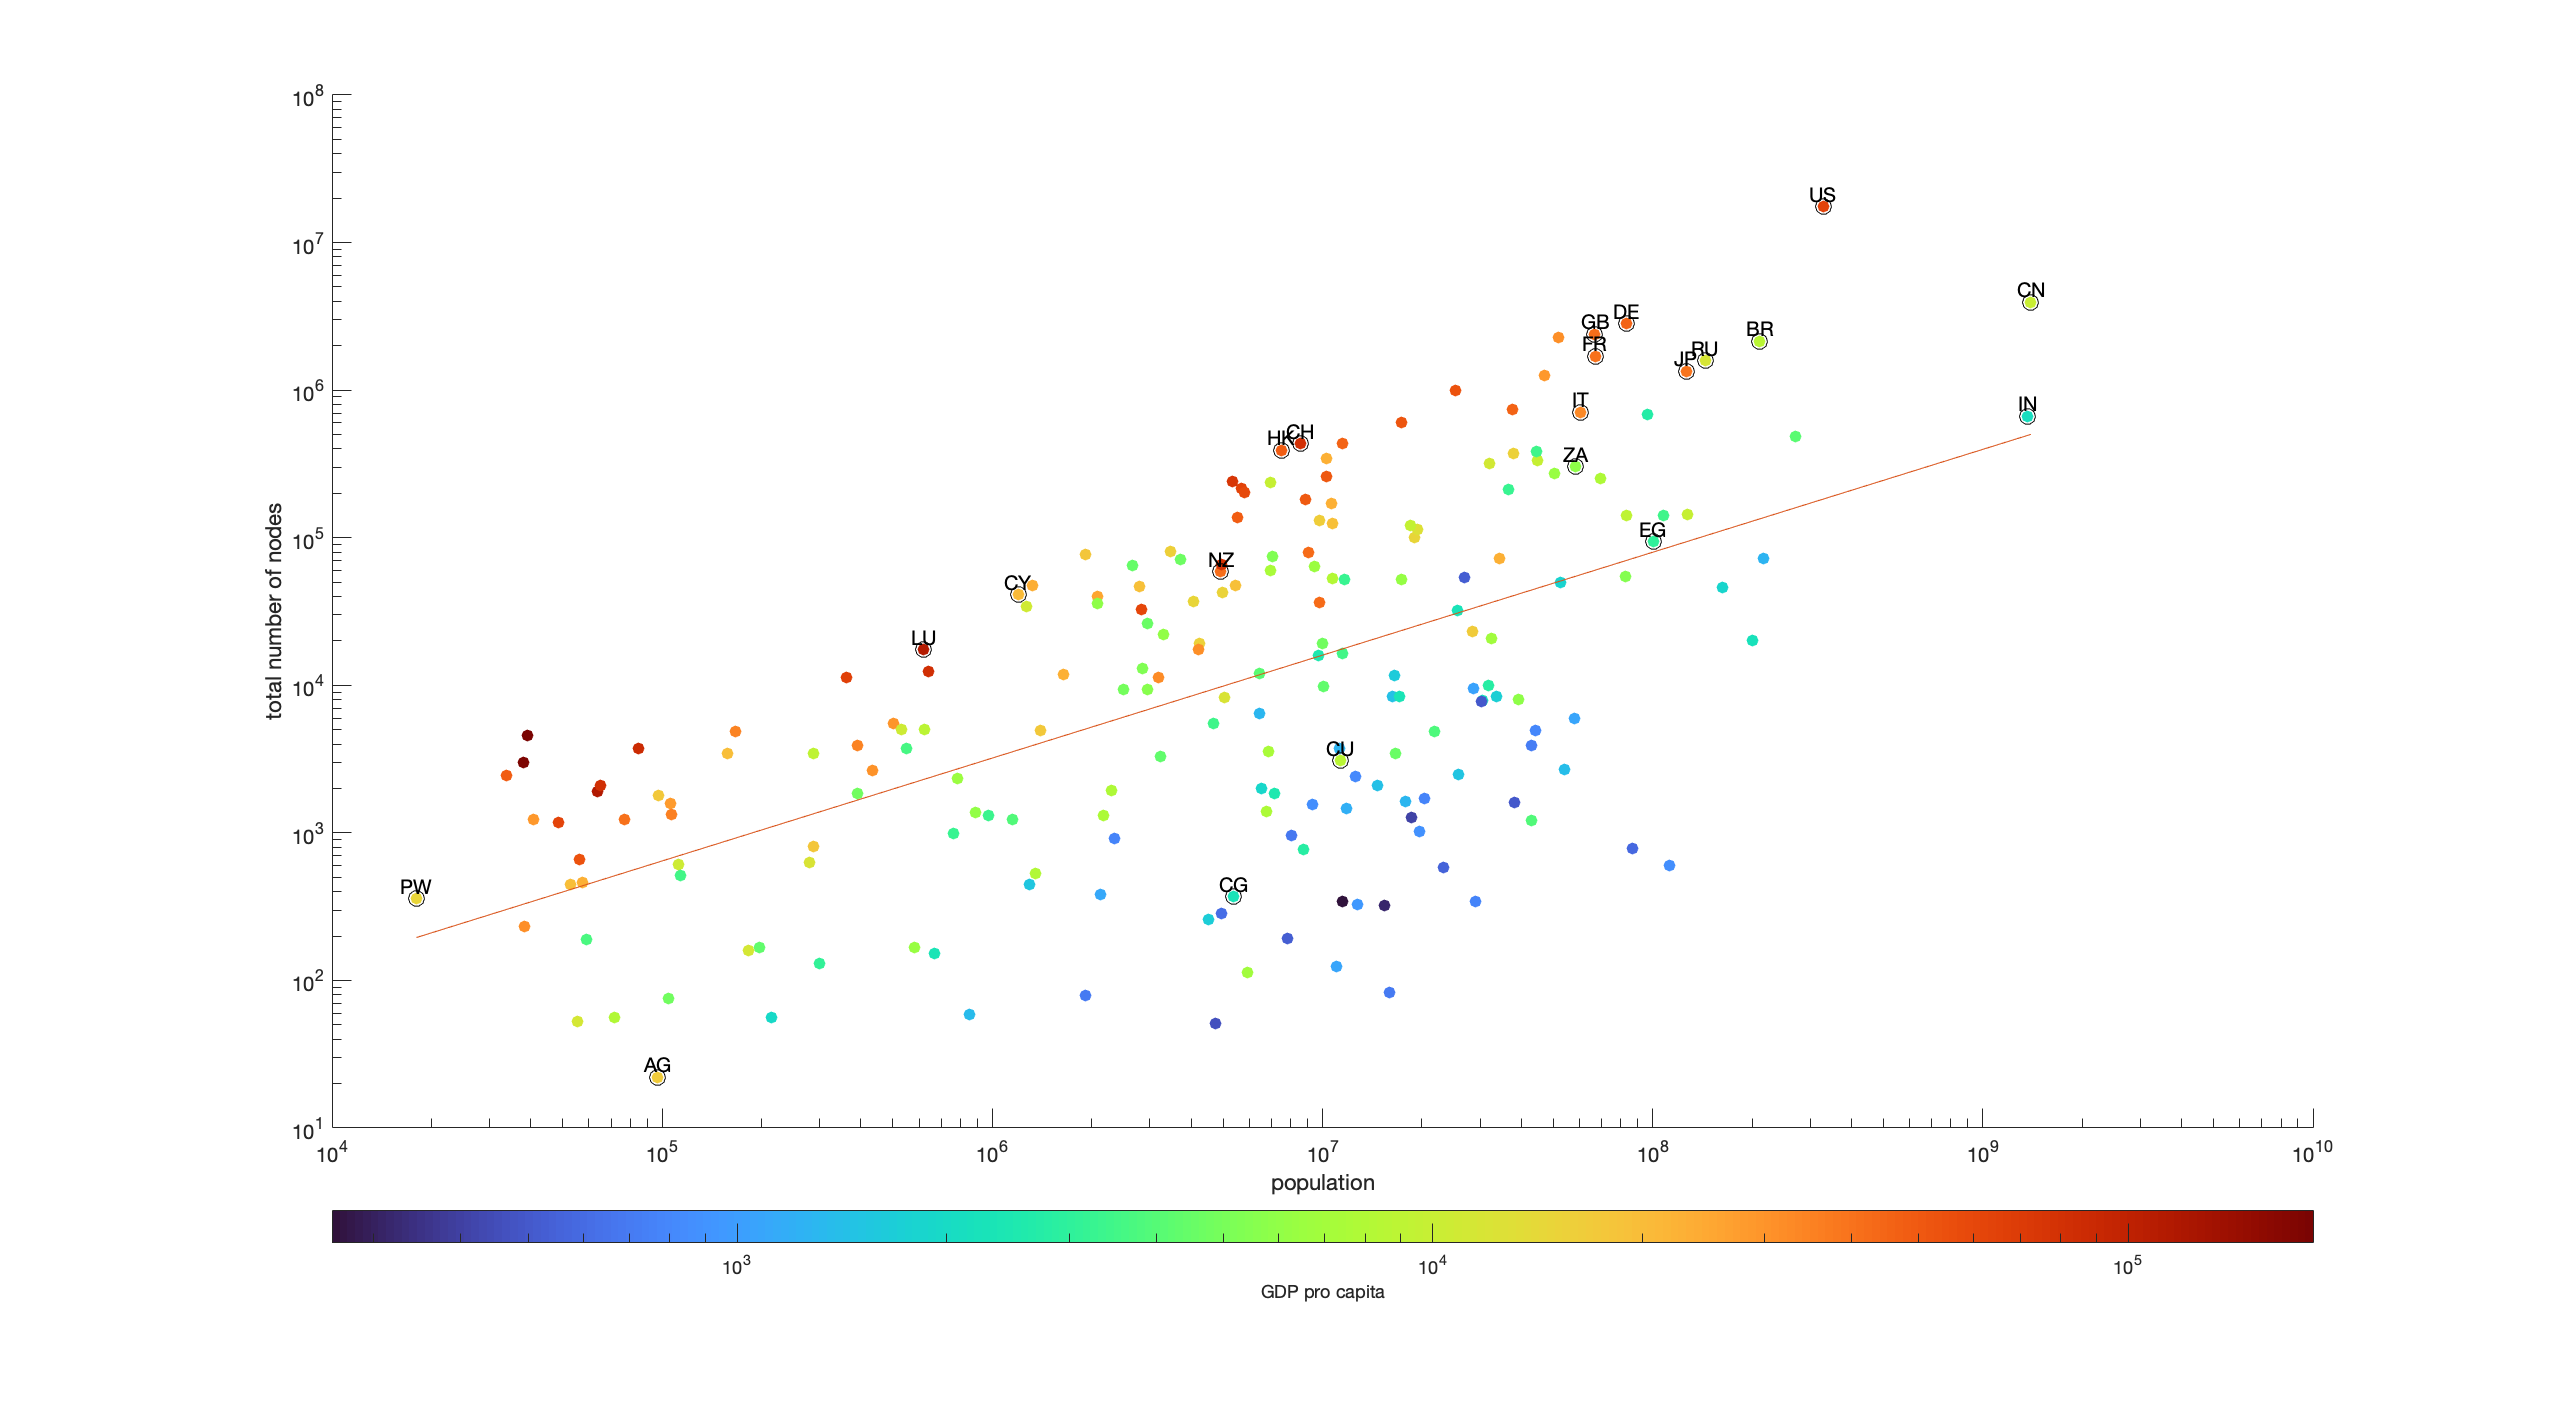

clf
% scatter plot
figure('Position', [10 10 1920 1068])
pop = lcc_pop_gdp_country.population;
tot_nodes = lcc_pop_gdp_country.count .* lcc_pop_gdp_country.largest_cc_size;
gdp = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
scatter(pop, tot_nodes, [], gdp, "filled")
set(gca, 'YScale', 'log', 'XScale', 'log', 'ColorScale','log')
colormap turbo
c = colorbar('southoutside');
c.Label.String = "GDP pro capita";
xlabel("population")
ylabel("total number of nodes")

% highlight specific countries
countries = ['BR' "CN" "DE" "FR" "IN" "IT" "JP" "RU" "US" "CG" "CH" "CU" "CY" "EG" "GB" "NZ" "ZA" "HK" "LU" "AG" "PW"];
size = 100;
hold on
for i = 1:length(countries)
    country = countries(i);
    T = lcc_pop_gdp_country(country,:);
    plot(T.population, T.count * T.largest_cc_size, "Marker","o", "MarkerSize", 8, "Color", "black")
    text(T.population, T.count * T.largest_cc_size, country,'VerticalAlignment','bottom','HorizontalAlignment','center', "Color","black", "FontSize",10)
end

% regression line
X=log10(pop); Y=log10(tot_nodes);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([pop(i1) pop(i2)],yhat) % add fitted line
hold off

number of different ASs vs total number of nodes colored by GDP

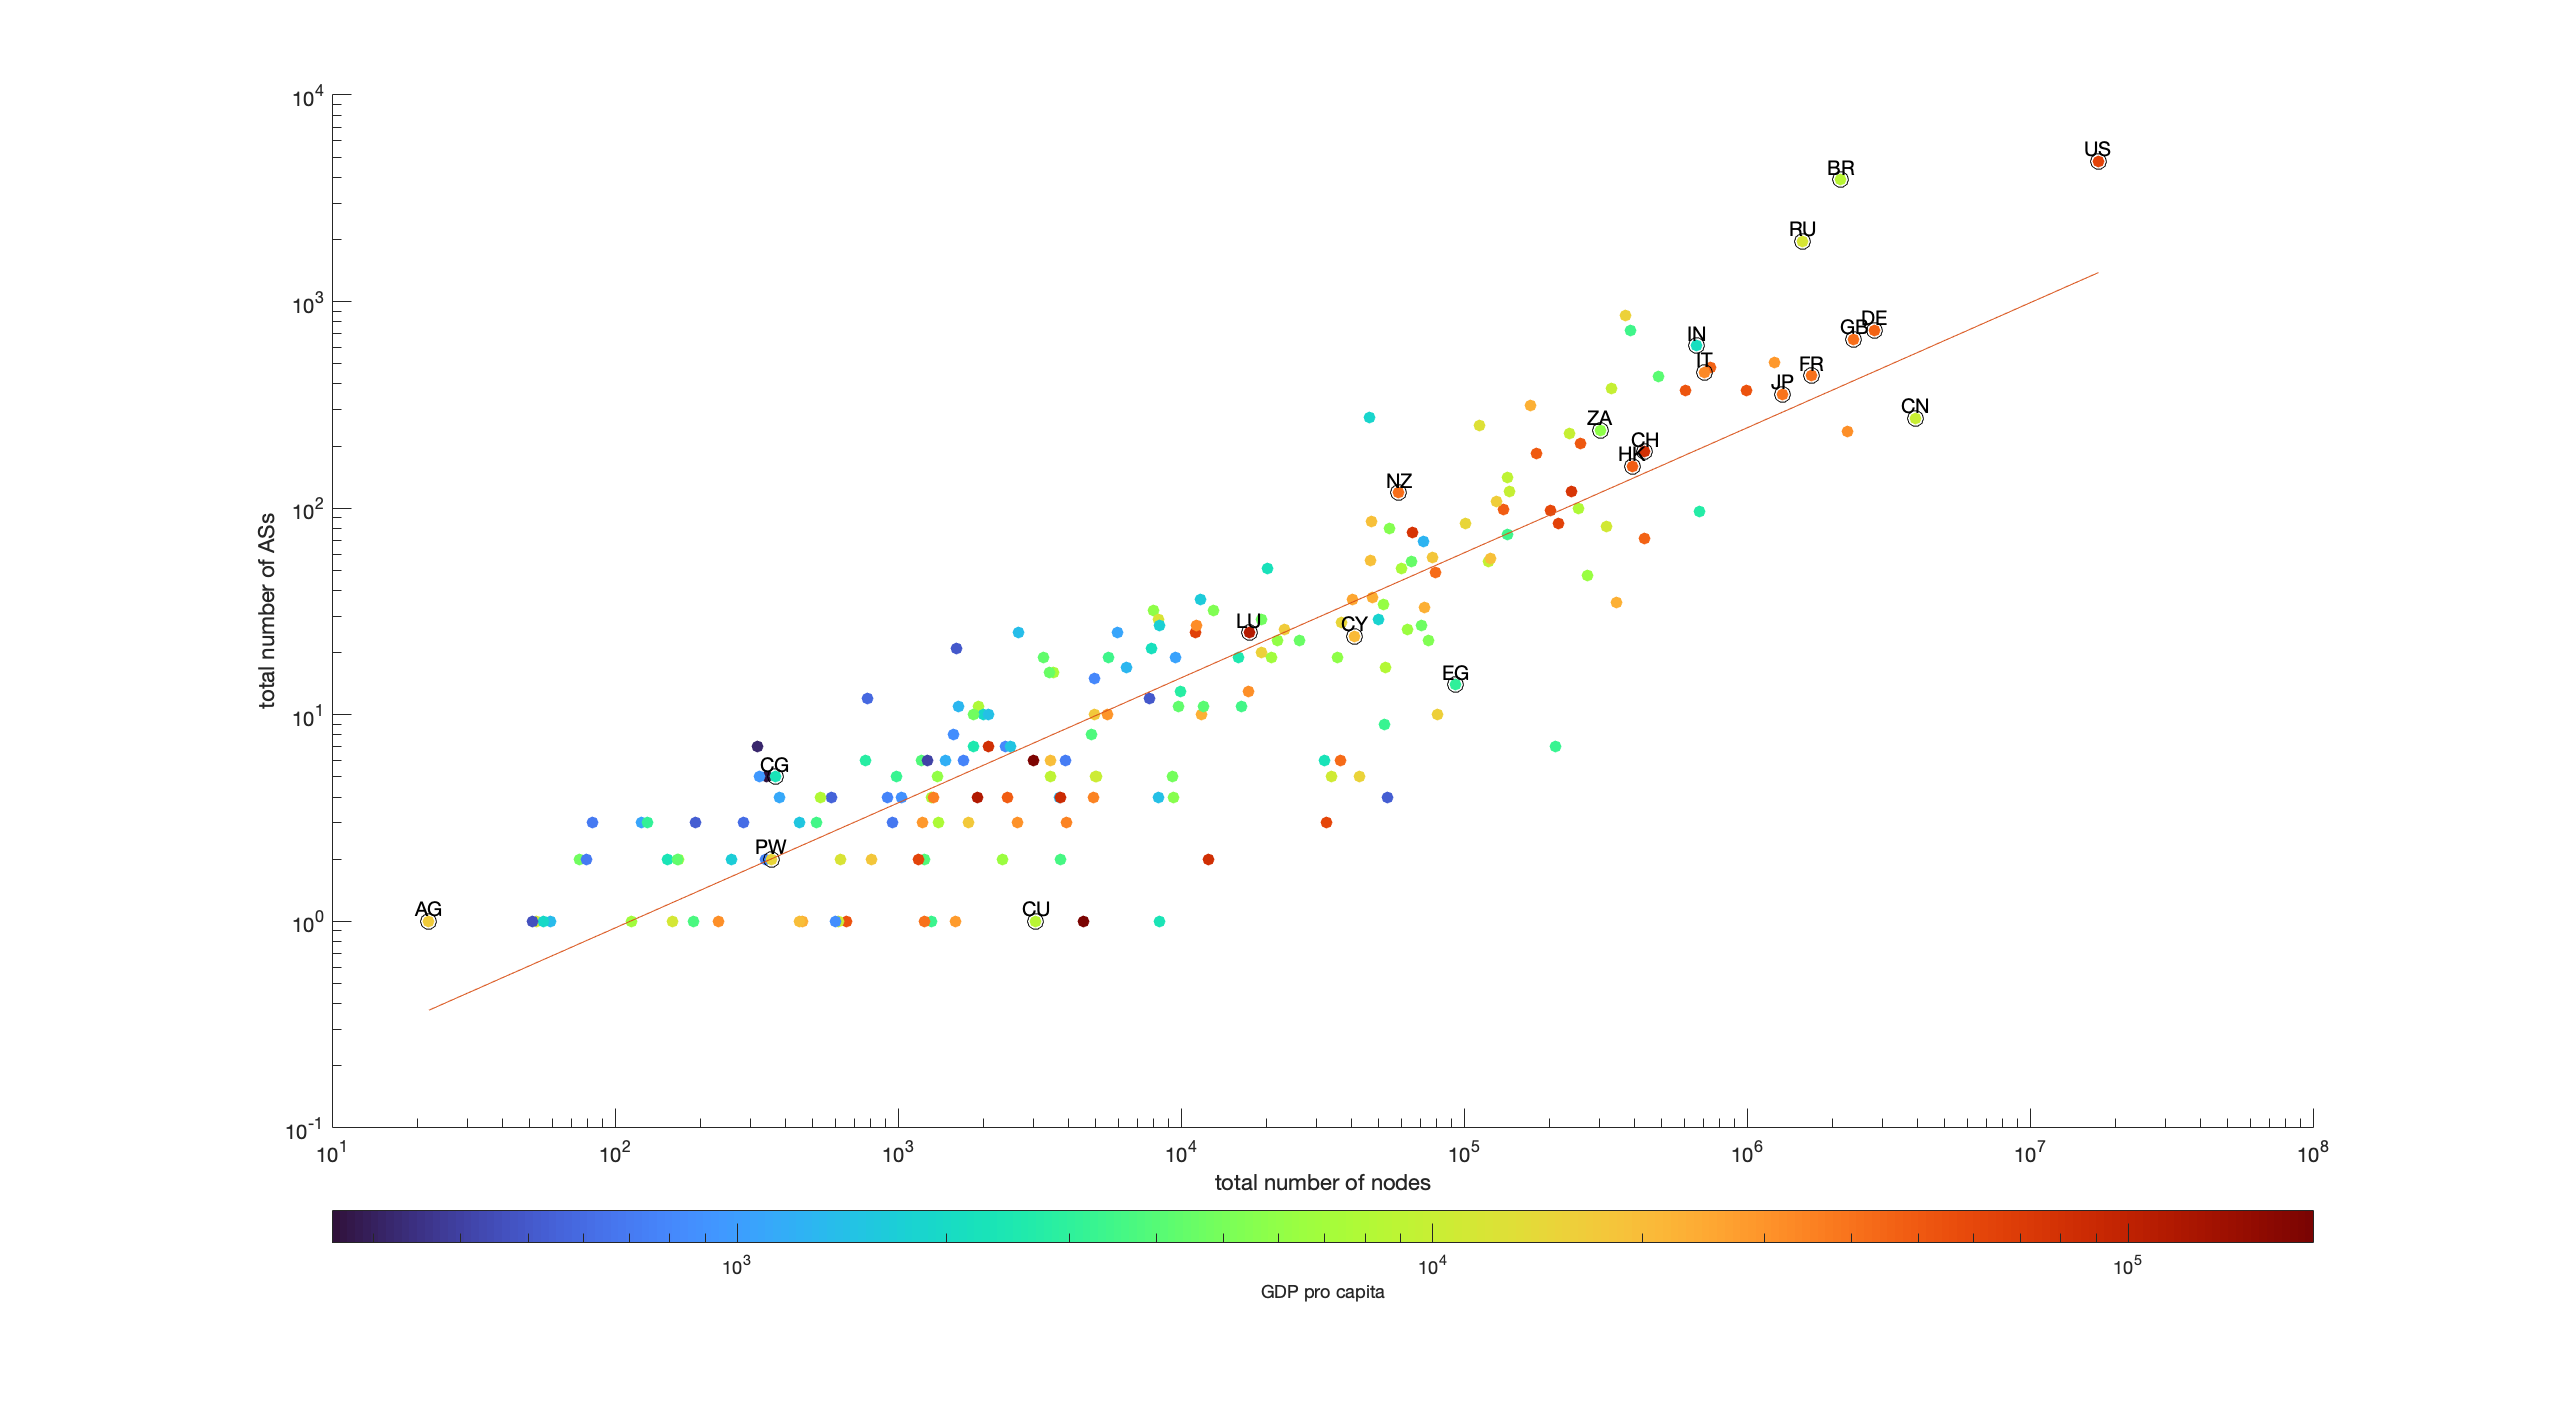

clf
% scatter plot
figure('Position', [10 10 1920 1068])
as_count = lcc_pop_gdp_country.count;
tot_nodes = lcc_pop_gdp_country.count .* lcc_pop_gdp_country.largest_cc_size;
gdp = lcc_pop_gdp_country.gdp ./ lcc_pop_gdp_country.population;
scatter(tot_nodes, as_count, [], gdp, "filled")
set(gca, 'YScale', 'log', 'XScale', 'log', 'ColorScale','log')
% lsline
colormap turbo
c = colorbar('southoutside');
c.Label.String = "GDP pro capita";
xlabel("total number of nodes")
ylabel("total number of ASs")

% highlight specific countries
countries = ['BR' "CN" "DE" "FR" "IN" "IT" "JP" "RU" "US" "CG" "CH" "CU" "CY" "EG" "GB" "NZ" "ZA" "HK" "LU" "AG" "PW"];
size = 100;
hold on
for i = 1:length(countries)
    country = countries(i);
    T = lcc_pop_gdp_country(country,:);
    plot(T.count * T.largest_cc_size, T.count, "Marker","o", "MarkerSize", 8, "Color", "black")
    text(T.count * T.largest_cc_size, T.count, country,'VerticalAlignment','bottom','HorizontalAlignment','center', "Color","black", "FontSize",10)
end

% regression line
X=log10(tot_nodes); Y=log10(as_count);  % convert both variables to log's
b=polyfit(X,Y,1);        % estimate coefficients
[x1,i1] = min(X);       % find endpoints
[x2,i2] = max(X);
yhat=10.^[polyval(b,[x1 x2])];  % evaluate at end points
loglog([tot_nodes(i1) tot_nodes(i2)],yhat) % add fitted line
hold off